dsp3

Q1

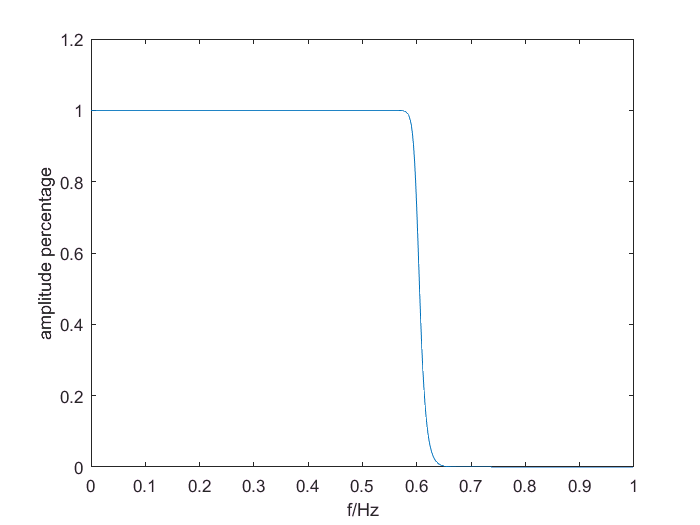

figure(1);
fn=2;
wp=0.6/(fn/2);ws=0.62/(fn/2);
rp=3;rs=20;
[n,wn]=buttord(wp,ws,rp,rs);
[b,a]=butter(n,wn);
[h,w]=freqz(b,a);
plot(w/pi*(fn/2),abs(h));
xlabel('f/Hz');ylabel('amplitude percentage');

Q2

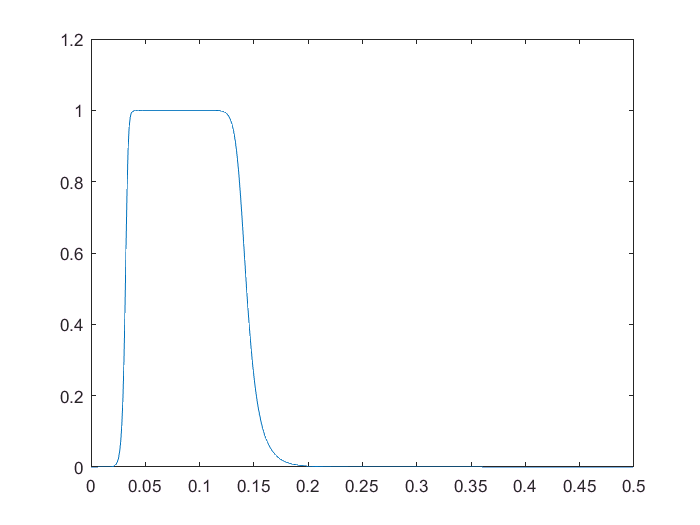

% figure(2);
% fcutlow = 0.03;   %low cut frequency in Hz
% fcuthigh = 0.15;   %high cut frequency in Hz
% fs = 1;
% [b,a]=butter(6,[fcutlow,fcuthigh]/(fs/2),'bandpass');
fn=1;
wp=[0.03/(fn/2),0.15/(fn/2)];ws=[0.02/(fn/2),0.16/(fn/2)];
rp=12;rs=21;
[N,wn]=buttord(wp,ws,rp,rs);
[b,a]=butter(N,wn);
[h,w]=freqz(b,a);
plot(w/pi*(fn/2),abs(h));

% freqz(b, a);

loading input data for further filtering

fid=fopen('S0037-130419-120000-A','r','ieee-le');
para128=fread(fid,[128,1],'char');
para128s=para128(para128~=0);               %Remove the unused bytes
[equmtname2,reststr1]=strtok(para128s,'-'); %Get instrument number in characters
[yymmdd2,reststr2]=strtok(reststr1,'-');    %Get yymmdd in characters
[hhmmss2,reststr3]=strtok(reststr2,'-');    %Get hhmmss in characters
%Get latitude(N)stla_N
[stla,reststr1]=strtok(reststr3,'-');       %Get latitude in characters
%'Nddmm.mmm'
%Characters to double
stla_1=stla(2:length(stla));                %Remove 'N'       
[stla_2,stla_3]=strtok(stla_1,'.');         %Get ddmm and mmm in characters
stla_4=str2double(char(stla_2));            %String 'ddmm' to double 
stla_3N=str2double(char(stla_3));           %String '.mmm' to double (decimal)
stla_N=floor(stla_4/100)+(mod(stla_4,100)+stla_3N)/60;
%Get longitude(E)stlo_E
[stlo,params]=strtok(reststr1,'-');         %Remove 'E' 
%'Edddmm.mmm'（one more character than latitude）
%Characters to double
stlo_1=stlo(2:length(stlo));
[stlo_2,stlo_3]=strtok(stlo_1,'.');
stlo_4=str2double(char(stlo_2));
stlo_3E=str2double(char(stlo_3));
stlo_E=floor(stlo_4/100)+(mod(stlo_4,100)+stlo_3E)/60;
%Get n1~n8
[A,reststr1]=strtok(params,',');           
[n1,reststr2]=strtok(reststr1,',');        %n1_Num:working channel number
n1_Num=str2double(char(n1));               %string to double
[n2,reststr1]=strtok(reststr2,',');        %n2_Num:number of all the channels
n2_Num=str2double(char(n2));
[n3,reststr2]=strtok(reststr1,',');        %n3_Num:sampling frequency in Hz
n3_Num=str2double(char(n3));
[n4,reststr1]=strtok(reststr2,',');        %n4_Num:gain
n4_Num=str2double(char(n4));
[n5,reststr2]=strtok(reststr1,',');        %n5_Num:height
n5_Num=str2double(char(n5));
[n6,reststr1]=strtok(reststr2,',');        %n6_Num:humidity
n6_Num=str2double(char(n6));
[n7,reststr2]=strtok(reststr1,',');        %n7_Num:temperature
n7_Num=str2double(char(n7));
n8=reststr2(2:length(reststr2));           %n8_Num:file length in byte
n8_Num=str2double(char(n8));
data_length=(n8_Num-128)/2;                %Calculate the length of data
data_all=fread(fid,[data_length,1],'int16');

now that the entire subsonic dataset has benn loaded into our working-space

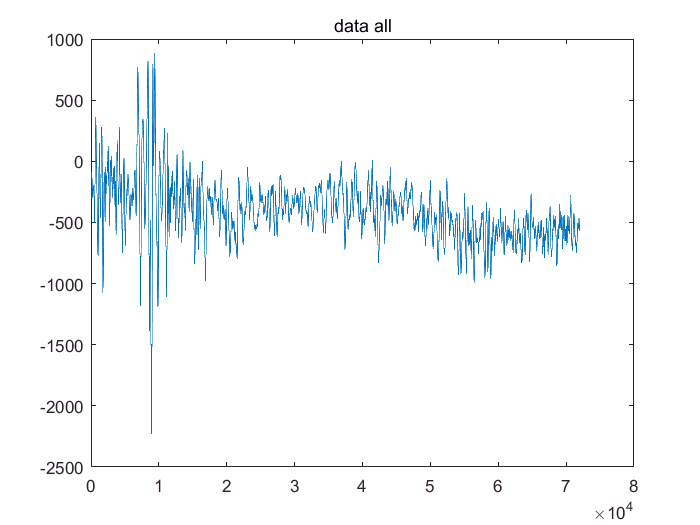

% quake_section = data_all(42600:44600,:);
% dataOut = filter(b,a,quake_section);

n=0:length(data_all)-1;

figure(3);
plot(n,data_all');
title('data all');

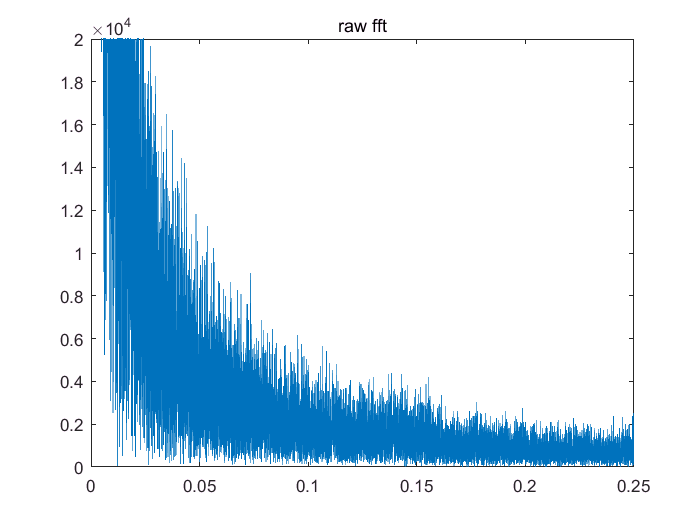


figure(4);
raw_fft = fft(data_all');
normalized_n = (n*1/72000);
abs_raw_fft = abs(raw_fft);
plot(normalized_n(1:18000), abs_raw_fft(1:18000));
axis([0 0.25 0 20000]);
title('raw fft');

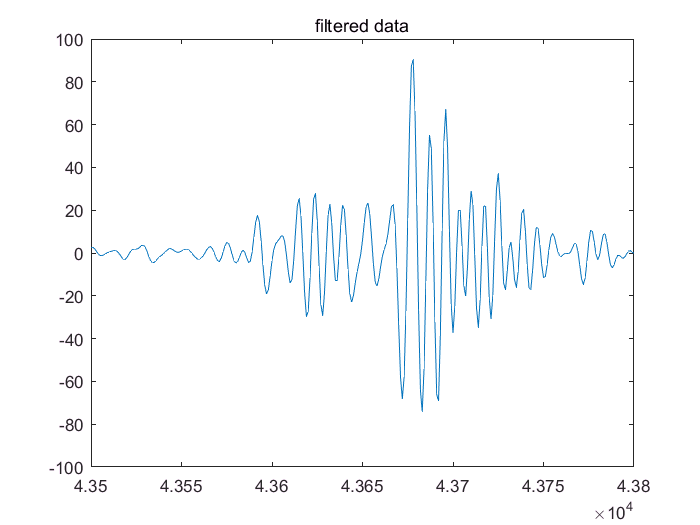


figure(5);
x=filter(b,a,data_all');
plot(n,x);axis([43500 43800 -100 100]);
title('filtered data');

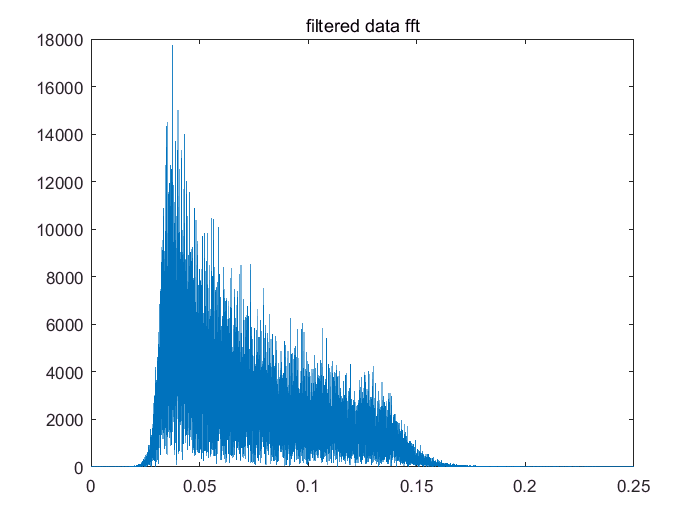


figure(6);
x_fft = fft(x);
abs_x_fft = abs(x_fft);
plot(normalized_n(1:18000), abs_x_fft(1:18000));
title('filtered data fft');

% subplot(2,1,1);plot([1:length(quake_section)],quake_section);title('raw data');
% subplot(2,1,2);plot([1:length(quake_section)],dataOut);title('filtered data');

Q3

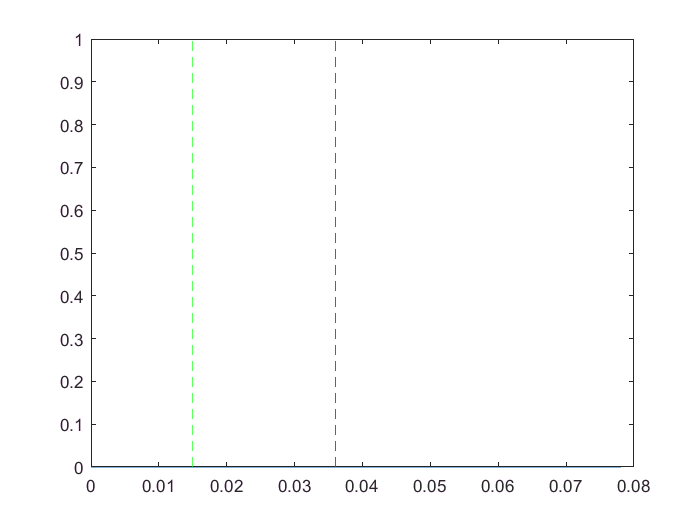

figure(7);
fn = 20;
wp = [0.015/(fn/2), 0.036/(fn/2)];
ws = [0.01/(fn/2), 0.041/(fn/2)];
rp = 0.1;
rs = 0.2;
% [N,wn]=buttord(wp,ws,rp,rs);
[b,a]=butter(N,wn);
[h,w]=freqz(b,a);
plot((w(1:5))/pi*(fn/2),abs(h(1:5)));
hold on;
line([0.015,0.015], [0 1],'linestyle','--','Color','g');
line([0.036,0.036], [0 1],'linestyle','--','Color','r');

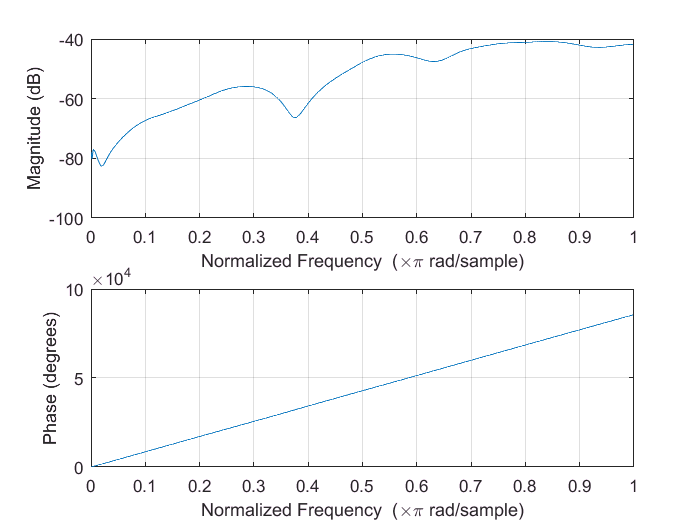

freqz(h,w)

loading data of the seismic wave

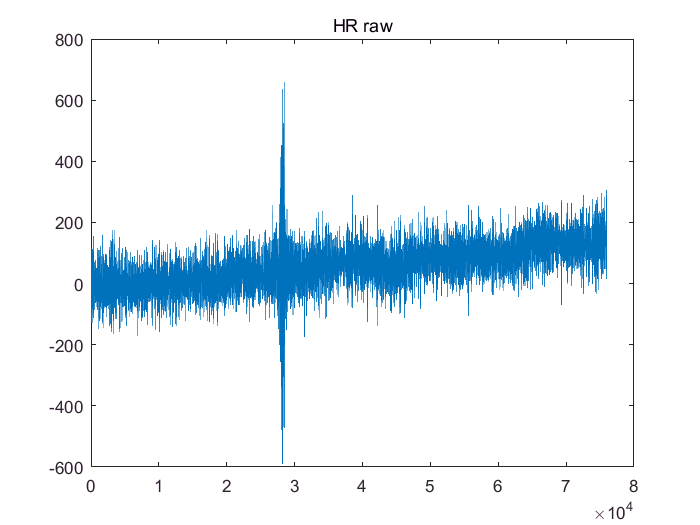

fid=fopen('XAN.BHZ.00.ori.SAC','r','ieee-le');
A=fread(fid,[70,1],'float32');
B=fread(fid,[40,1],'int32');
C=char(fread(fid,[1,192],'char'));
HR=fread(fid,'float32');
A(A==-12345.0)=NaN;
B(B==-12345)=NaN;
fclose(fid);

figure(8);
n=0:length(HR)-1;
plot(n, HR');
title('HR raw');

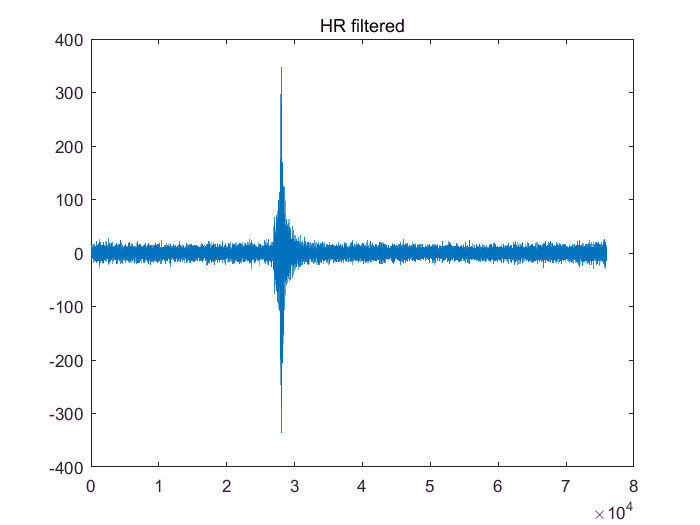


figure(9);
x_HR = filter(b, a, HR');
plot(n,x_HR);
title('HR filtered');

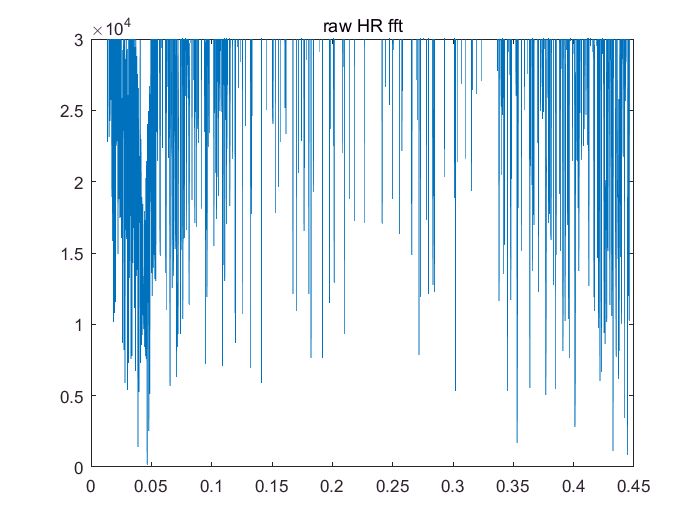


figure(10);
HR_raw_fft = fft(HR');
normalized_n = (n*20/76001);
abs_raw_HR_fft = abs(HR_raw_fft);
plot(normalized_n(1:1700), abs_raw_HR_fft(1:1700));
axis([0 0.45 0 3*10^4]);
title('raw HR fft');

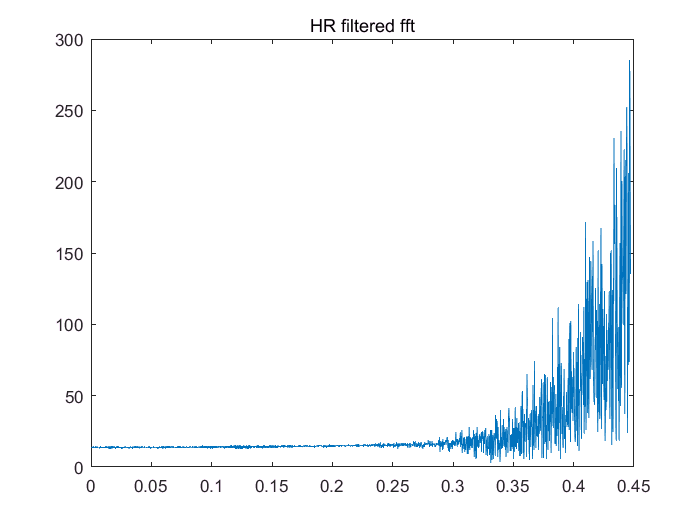


figure(11);
x_HR_fft = fft(x_HR);
abs_x_HR_fft = abs(x_HR_fft);
plot(normalized_n(1:1700), abs_x_HR_fft(1:1700));
title('HR filtered fft');

Q4

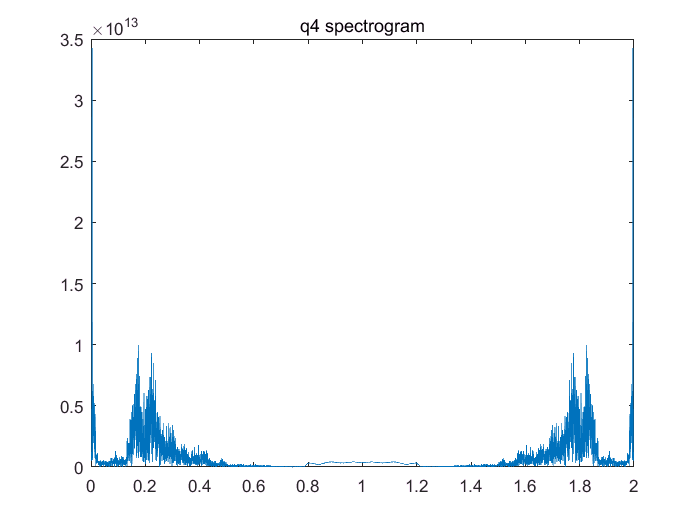

figure(12);
fid=fopen('Force.Z.SAC','r','ieee-le');
A=fread(fid,[70,1],'float32');
B=fread(fid,[40,1],'int32');
C=char(fread(fid,[1,192],'char'));
q4_HR=fread(fid,'float32');
A(A==-12345.0)=NaN;
B(B==-12345)=NaN;
fclose(fid);

q4_freq = fft(q4_HR');
abs_q4_fft = abs(q4_freq);
n=0:length(q4_HR)-1;
normalized_n = (n*2/6023);
plot(normalized_n, abs_q4_fft);
title('q4 spectrogram');

compute the signal power information

[st_matrix] = st(q4_HR);

 
Minfreq = 0
Maxfreq = 3011
Sampling Rate (time   domain) = 1
Sampling Rate (freq.  domain) = 1
The length of the timeseries is 6023 points
 
The number of frequency voices is 3012
Estimated time is 2.252813
Calculating S transform...
Finished Calculation
